# Project 2 Report

## Objective

Designing a control system for provided plant, which has sensor in loop for feedback.

Designed system should have less than 5% of overshoot ($\%MP$), less than 3 sec of settling time ($t_s$) for system to be settling within 1% and steady state error ($e_{ss}$) with respect to reference is less than 5%.

Sensor provided has the DC gain ($K_{dc}$) of 1 and time constant ($\tau$) of 0.1sec, once the controller developed satisfies the system requirement for the provided sensor, using the control law designed, system response is to be checked for the second sensor with DC gain ($K_{dc}$) of 1 and time constant of ($\tau$) of 0.2 sec, and if required redesigning the system to meet the earlier requirements shared.

## Introduction

Provide transfer function for the plant is as below-


$$G_{plant} = \frac{Y}{U} = \frac{25}{s^2+4s+25}$$


for sensor details provided are as below-

dc gain is 1 and time constant for sensor is 0.1 sec.

From the details available transfer function for sensor will be-


$$G_s = \frac{K_{dc}}{{\tau}s + 1} = \frac{1}{0.1s+1}$$


where, $ K_{dc}$ is DC gain

and $\tau$ is time constant.

We also have second sensor with time constant of 0.2 and DC gain of 1, whose transfer function will be as below-


$$G_{s_2} = \frac{1}{0.2s+1}$$


%% Cleanup
clearvars           % Clearing variables
close('all')        % Close all the figures

%% Defining the plant details as provided
num1 = 25;          % Numerator of plant
den1 = [1 4 25];    % Denominator of plant

mytfpl = tf(num1,den1)


mytfpl =
 
        25
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.




%% Defining the sensor details as provided
kdc = 1;            % dc gain for sensor
tau = 0.1;          % Time constant for original sensor
tau2 = 0.2;         % Time constant for second sensor

nums = [kdc];       % numerator for sensor transfer function
dens = [tau 1];     % Denominator for sensor transfer function

mytfs = tf(nums,dens)


mytfs =
 
      1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



%% Generating transfer function for the second sensor
tau2 = 0.2;
mytfs2 = tf(kdc,[tau2 1]);

## Stability Check for System with Proportional Controller

a) Without considering Sensor dynamics system, system will be a unity feedback with proportional controller. Representation for the system can be done as below-

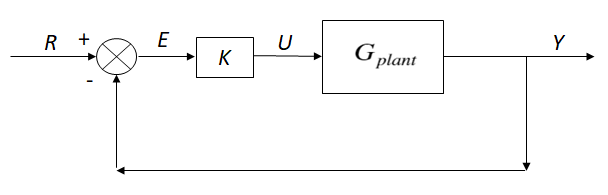

The equation for the system will be-


$$G_{cl1} = \frac{KG_{plant}}{1+KG_{plant}}$$



$$G_{cl1} = \frac{{\frac{25K}{s^2+4s+25}}}{1+{\frac{25K}{s^2+4s+25}}$$



$$G_{cl1} = \frac{{25K}}{s^2+4s+25(K+1)}$$


Characteristic equation for the close loop is-


$$s^2+4s+25(K+1) = 0$$


Using Routh criteria stability, we get


$$s^2: 1\ \  25(K+1)
$$



$$s^1:4\ \ 0$$



$$s^0:25(K+1)$$


For system to be stable all values in the first column should not change sign and greater than zero.


$$25(K+1) > 0$$


hence, we get condition for stability as,


$$K>-1$$
 

b) By considering sensor dynamics, system with proportional controller can be represented as below-

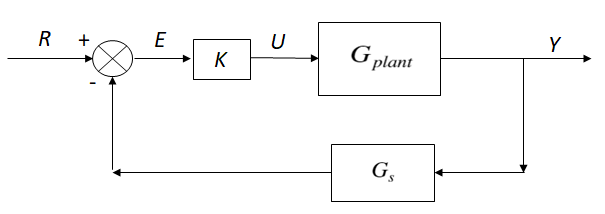

By Block diagram reduction, we get,


$$(R-YG_s)KG_{plant} = Y$$



$$RKG_{plant} = Y(1+KG_sG_{plant})$$



$$\frac{Y}{R} = \frac{KG_{plant}}{1+KG_sG_{plant}$$


substituting the values for

$G_{plant}=\frac{25}{s^2+4s+25}$ and $G_s = \frac{1}{0.1s+1}$

We get,


$$\frac{Y}{R} = \frac{\frac{25K}{s^2+4s+25}}{1+\frac{25K}{s^2+4s+25}*\frac{1}{0.1s+1}$$


Hence, by solving the above equation we get-


$$\frac{Y}{R} = \frac{25K(0.1s+1)}{0.1s^3+1.4s^2+6.5s+25+25K}$$


Hence characteristic equation for the system is-


$$0.1s^3+1.4s^2+6.5s+25(K+1) = 0$$


Using Routh's criteria for stability,


$$s^3: 0.1\ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ 6.5$$



$$s^2:1.4\ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  25(K+1)$$



$$s^1:\frac{(1.4)(6.5)-(0.1)(25(K+1))}{1.4}$$



$$= \frac{6.6-2.5K}{1.4}$$



$$s^0:25(K+1)$$


For system to be stable all values in the first column should not change sign and greater than zero.

for $s^0$ we have, $25(K+1) > 0$

hence, $K>-1$

 for $s^1$ we have, $\frac{6.6 -2.5K}{1.4}>0$

By solving we get,


$$2.64>K$$


From the two conditions we have, we get the stability criteria for the system as-


$$-1<K<2.64$$


By looking at the two condition, for system with sensor dynamics range of $K$ is substantially reduced from earlier range of K. By adding the sensor dynamics, characteristic equation for system became third order as compared to earlier second order system, providing a new pole in the left half plane which is away from the conjugate pole pair, but has the effect regarding stability of the system, limiting the range of gain for the proportional controller.

Hence during the control design sensor dynamics required to be included to keep eye on the stability of the system designed and obtaining the results required. 

To cross verify the results obtained from the stability criteria, below Simulink model was prepared and results for same are provided below-

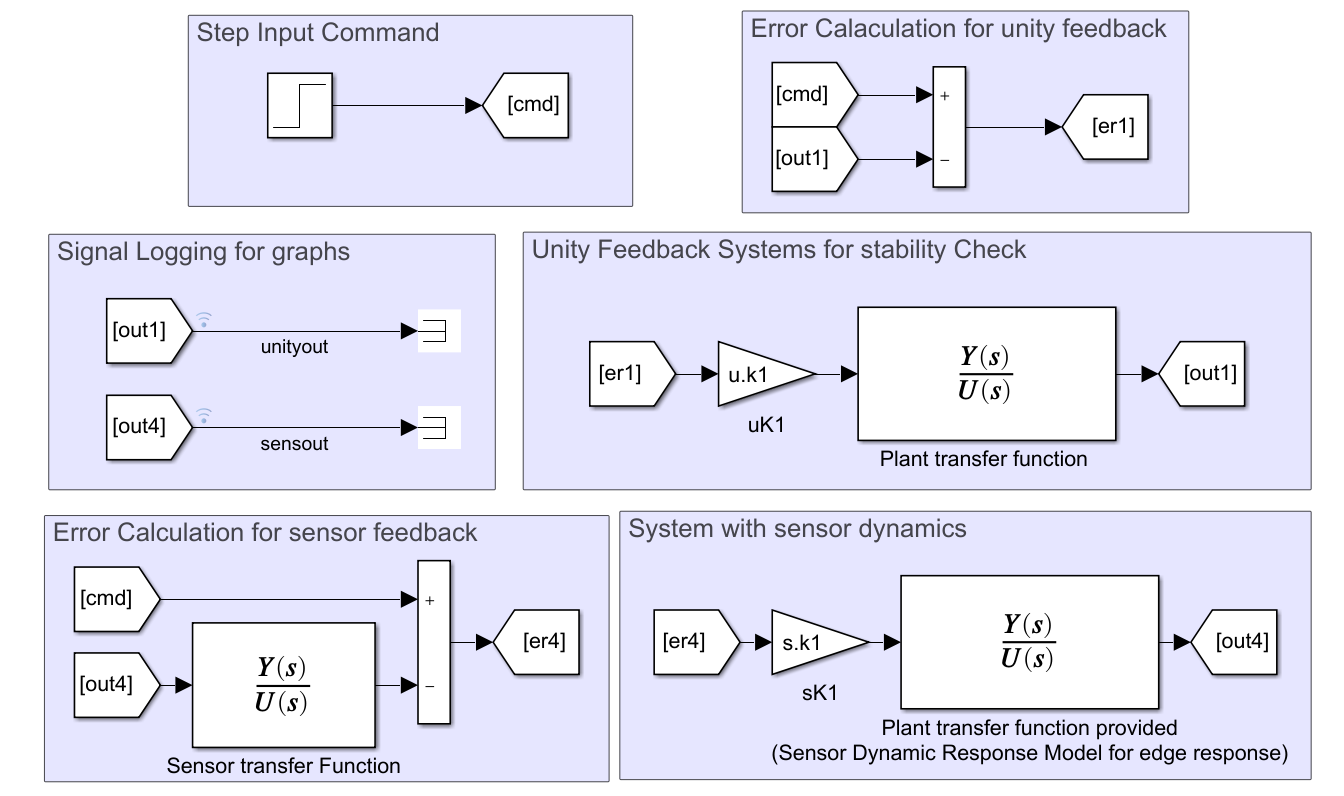

Below Are details of the output observed from for different conditions-

For unity feedback system with gain $K = 5$ in stability range below response was observed-

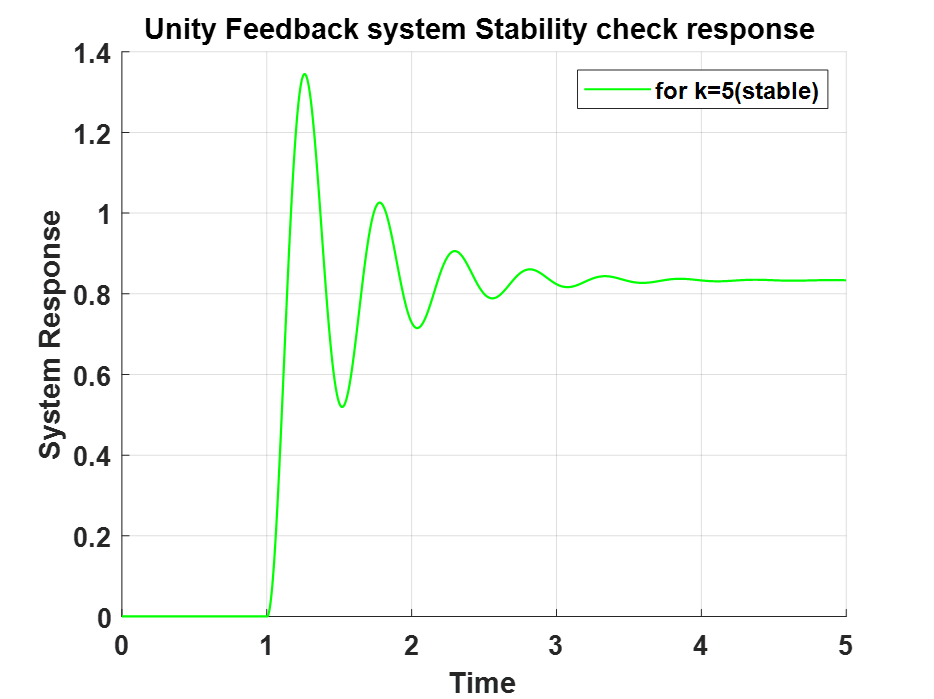

for unity feedback with $K = -1$, response observed was as below, at which system starts to become unstable-

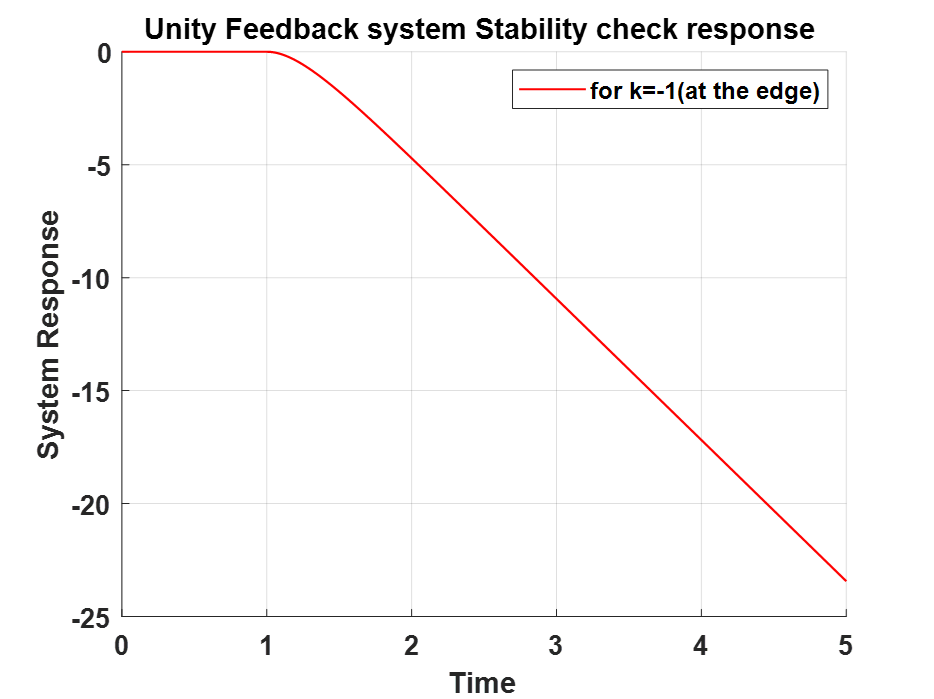

With sensor dynamics, within the provided range response for value of $K = 0.5$ observed as below,

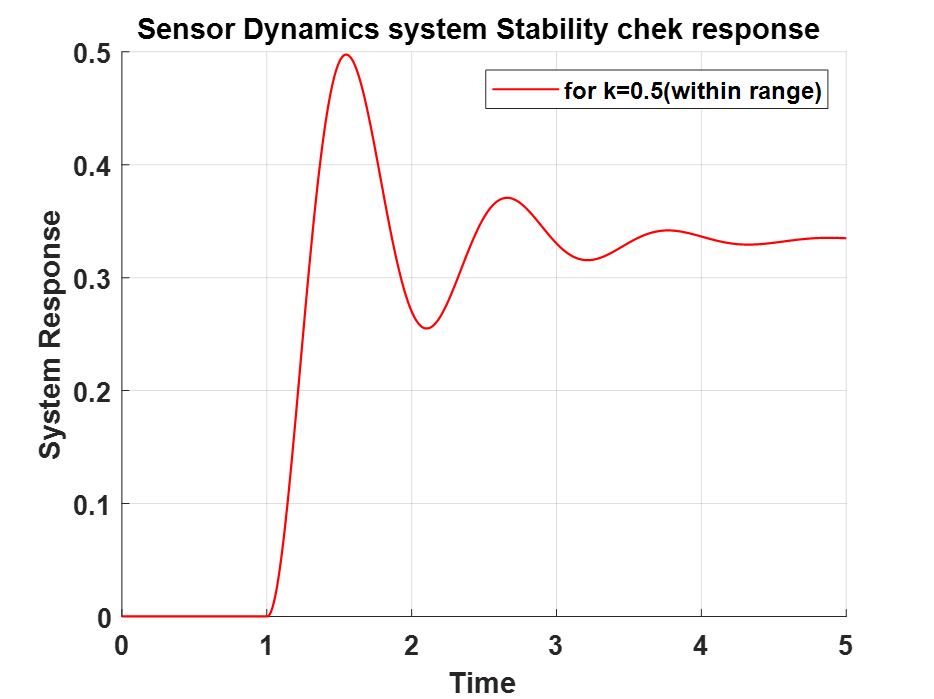

With sensor dynamics for provided range response for the value $K = 4$ observed as below,

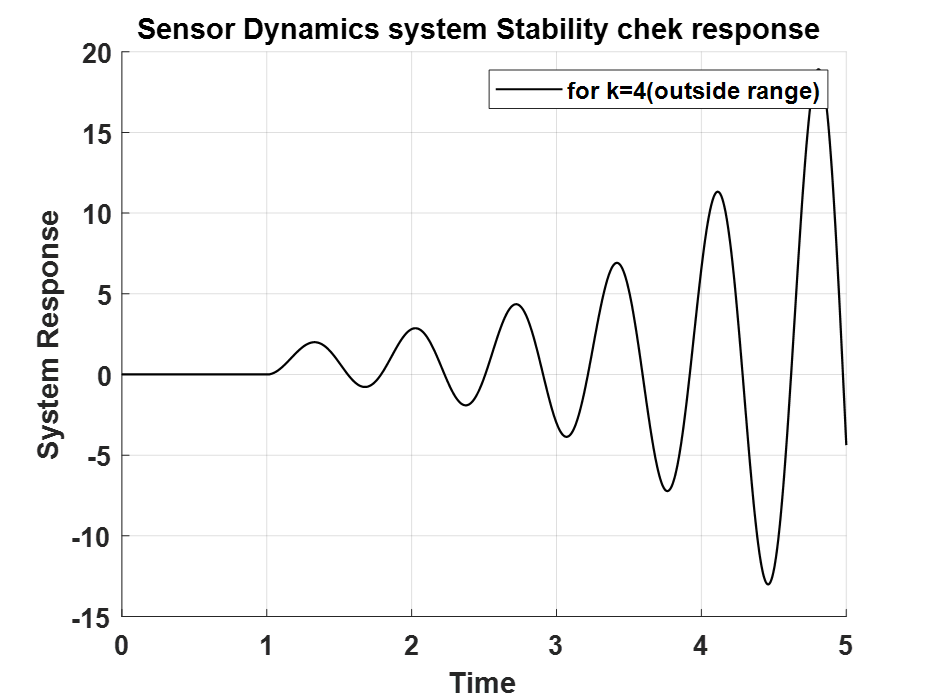

From the Simulink model outputs, earlier criteria obtained from Routh array are being followed. 

## Design of Controller as per System Requirement

Requirements provided are as below-

Steady state error is required to be less than 5%, Percent overshoot is required is less than 5% and settling time required is less than 3 sec for 1% settling and actuator force not to exceed maximum force +/- 2.5N.

With earlier requirement and Simulink model output steady state error with unit feedback system observed to be around 50% as transfer function for the unity feedback is-

As we have design system with sensor of time constant 0.1 and unity DC gain.

1) Controller design using Proportional controller for the sensor dynamics-

First we must check for system stability criteria and steady state error in system

we have, $G_{plant} = \frac{25}{s^2+4s+25}$ and $G_{s2}=\frac{1}{0.1s+1}$

block diagram for system with new sensor and proportional controller would be-

By Solving for closed loop transfer function for the system we get,$\frac{Y}{R} = \frac{KG_{plant}}{1+G_sG_{plant}K$

And by substituting the above values we get function as,


$$\frac{Y}{R} = \frac{25K(0.1s+1)}{(0.1s+1)(s^2+4s+25)+25K$$


from this we get characteristic equation as,

%% Multiplying two polynomials in denominator
temp = conv([0.1 1],[1 4 25])

temp =     0.1000    1.4000    6.5000   25.0000



$$0.1s^3+1.4s^2+6.5s+25(K+1) = 0$$


BY using Routh criteria, we get requirement for K as,


$$s^3: 0.1\ \ \ \ \ \ \ \ \ \ \ \ \ \ 6.5$$



$$s^2:1.4\ \ \ \ \ \ \ \ \ \ \ 25(K+1)$$



$$s^1:\frac{6.6-2.5K}{1.4}\ \ \ \ \ \ \ \ 0$$



$$s^0:25(K+1)$$


From routh criteria, for system to be stable all terms in the first column should have same sign and no sign change

$\frac{6.6-2.5K}{1.4}>0$ and $25(K+1)>0$

From the above two conditions, we get, requirement for $K$ as 


$$-1<K<2.64$$


To check for range of $K$to obtain the steady state error within requirement of less than $5\%$ of input value,

We have, $E = R - Y$

Assuming $R = \frac{1}{s^{q+1}$

We get, $E = \frac{1}{s^{q+1}} -\frac{1}{s^{q+1}}*\frac{25K(0.1s+1)}{0.1s^3+1.4s^2+6.5s+25(K+1)$


$$E = \frac{1}{s^{q+1}}\left(\frac{0.1s^3+1.4s^2+(6.6-2.5K)s+25}{0.1s^3+1.4s^2+6.6s+25(K+1)}\right)$$


for steady state error, we have $e_{ss} = \lim_{s\rightarrow0}{sE}$

for step input, substituting $q=0$ 

substituting above values in steady state error values, we get,


$$e_{ss}=\lim_{s\rightarrow0}s*\frac{1}{s}\left(\frac{0.1s^3+1.4s^2+(6.6-2.5K)s+25}{0.1s^3+1.4s^2+6.6s+25(K+1)}\right)$$



$$e_{ss} = \frac{1}{K+1}$$


Hence system is type $0$ for with proportional controller in system and will have a steady state error.

For steady state error requirement, we have $e_{ss_{req}}<5\%$, and considering step amplitude as 1, we get,$e_{ss_{req}}<0.05$

Hence, we get,


$$\frac{1}{K+1}<0.05$$



$$K>19$$


which is contradictory to the initial requirement for stability of system which was$-1<K<2.64$.

Hence only proportional controller will not work to obtain the requirement provided for the system.

2) Controller design using proportional and integral controller ($PI$)-

By using Proportional and integral controller for the system, we will be adding a pole at the origin in the system, which will make system type $1$ with respect to reference input and steady state error will be zero. It is generally true for unity feedback, hence checking same for current system by adding PI controller which will add pole at origin through controller.

With PI controller, system block diagram will be as below-

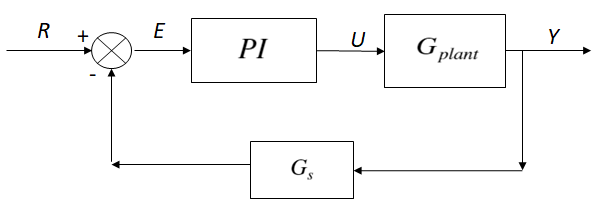

Closed loop transfer function for the system with block reduction is-


$$\frac{Y}{R} = \frac{PI*G_{plant}}{1+PI*G_s*G_{plant}$$


where, $PI = K_p+\frac{K_i}{s}$, $G_s = \frac{1}{0.1s+1}$ and $G_{plant} = \frac{25}{s^2+4s+25}$

By substituting, closed loop transfer function will be,


$$\frac{Y}{R} = \frac{25(sK_p+K_i)(0.1s+1)}{0.1s^4+1.4s^3+6.6s^2+25s(K_p+1)+25K_i$$
 

Checking for the steady state error for the closed loop function, to satisfy the requirment of $e_{ss_{req}}<0.05$ for unity step input.


$$E = R - Y$$


Assuming $R = \frac{1}{s^{q+1}$

We get, $E = \frac{1}{s^{q+1}} -\frac{1}{s^{q+1}}*\frac{25(sK_p+K_i)(0.1s+1)}{0.1s^4+1.4s^3+6.6s^2+25s(K_p+1)+25K_i$


$$E = \frac{1}{s^{q+1}}\left(\frac{s(0.1s^3+1.6s^2+4.1s+(25-5Ki)}{0.1s^4+1.4s^3+6.6s^2+25s(K_p+1)+25K_i}\right)$$



$$E = \frac{1}{s^{q}}\left(\frac{(0.1s^3+1.4s^2+4.1s+(25-5Ki)}{0.1s^4+1.4s^3+6.6s^2+25s(K_p+1)+25K_i}\right)$$


to calculate steady state error by final value theorem, we have,


$$e_{ss} = \lim_{s\rightarrow0}sE$$



$$e_{ss} = \lim_{s\rightarrow0}s *\frac{1}{s^{q}}\left(\frac{(0.1s^3+1.4s^2+4.1s+(25-5Ki)}{0.1s^4+1.4s^3+6.6s^2+25s(K_p+1)+25K_i}\right)$$


for $q = 0;$ we get, $e_{ss} = 0$;

for $q=1;$ we get $e_{ss} = \frac{25-5Ki}{25K_i}$

Hence, for any value of $K_i$ system type is $1$ except $K_i = 25/30$ for which system becomes type $2$.

For requirement of the steady state error for step input less than $5\%$, with PI controller steady state error for step input is zero. Satisfying the steady state error criteria.

For stability of system,

We have characteristic equation for the system as,


$$s^4: 0.1 \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \  \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ 6.5 \ \ \ \ \ \ \ \ \ \ \ 25K_i$$



$$s^3:1.4\ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ 25(K_p+1)\ \ \ \ \ \ \ \ \ 0 $$



$$s^2:\frac{1.4*6.5-5(K_p+1)}{1.4}\ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ \ 25K_i$$



$$\ \ \ =\frac{6.6-2.5K_p}{1.4}$$



$$s^1:\frac{165+102.5K_p-62.5K_p^2-49Ki}{6.6-2.5K_p}\ \ \ \ \ \ \ \ \ \ 0$$



$$s^0:25K_i$$


  For system stability we have from Routh criteria, in the first column there should not be sign change,

which gives, $25K_i>0$ , $\frac{165+102.5K_p-62.5K_p^2-49Ki}{6.6-2.5K_p}>0$ and $\frac{6.6-2.5K_p}{1.8}>0$

Hence, we get,

$K_p<2.64$, $K_i>0$ and $165+102.5K_p-62.5K_p^2>49K_i$

For stability system should satisfy the above conditions.

To design system for remaining requirements of the settling time$(t_s)$ less than 3sec for 1% settling and overshoot ($MP\%$) less than 5% using below MATLAB code for various iterations to obtain the values of $K_p$ and $K_i$ to obtain the values required.

Below is the code used to check for iterations of various values of $K_p$ and $K_i$, to satisfy the system requirements-

%% Defining requirements
ts = 3;             % Settling time
ST = 0.01;          % Settling requirement
MP = 5;             % Percentage overshoot

%% Calling transfer functions to cross check
mytfpl;
%%Cross verifying for the sensor with time constant 0.1
mytfs;
%% Setting values for the PIi controller
Kp = 0.025;
Ki = 1.2;

% Transfer function for PI controller
PI = tf([Kp Ki],[1 0]);
%% Finding closed loop transfer function
myfcls01 = feedback(PI*mytfpl,mytfs)


myfcls01 =
 
          0.0625 s^2 + 3.625 s + 30
  ------------------------------------------
  0.1 s^4 + 1.4 s^3 + 6.5 s^2 + 25.63 s + 30
 
Continuous-time transfer function.



S01 = stepinfo(myfcls01,'SettlingTimeThreshold',ST);
S01.Overshoot

ans = 0.0404

S01.SettlingTime

ans = 2.4679

Requirements provided for the system during design of $t_s$ less than 3sec for 1% settling, $\% MP$ less than 5% and steady state error ($e_{ss}$) less than 5% is achieved with PI controller for the gains of PI as $K_p$=0.025 and  $K_i$=1.2

Below are the details of the values iterated using the code above to satisfy the requirements of $\% MP$ and $t_s$ for tuning of PI controller-

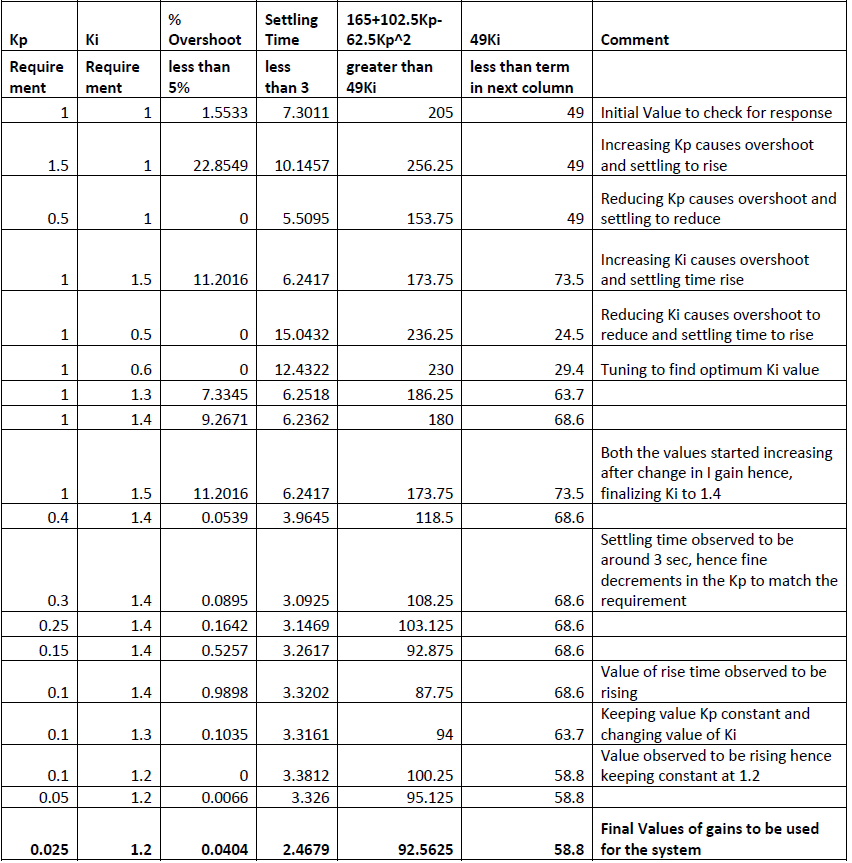

## Effect of Disturbance on the Designed System

With disturbance to the system block diagram for the system will be as below-

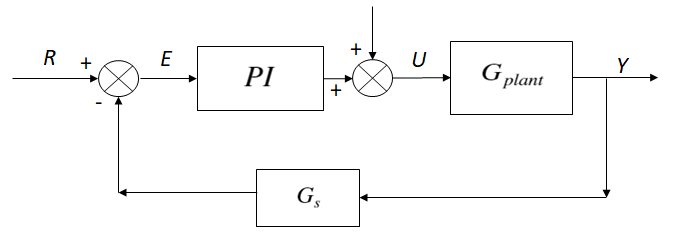

We have that with PI controller system type is $1$ with respect to reference input for the selected values of PI, hence it has zero error with respect to the step input and constant steady state error for the ramp input.

For checking system type with respect to disturbance introduced, is as below-

By solving with Block reduction, we get, system transfer function as,

 
$$((R-YG_s)PI + W)G_{plant} = Y$$



$$R*PI*G_{plant}+W*G_{plant} = Y(1+PI*G_s*G_{plant})$$



$$Y = \frac{PI*G_{plant}}{1+PI*G_s*G_{plant}}R+\frac{G_{plant}}{1+PI*G_s*G_{plant}}W$$


To check system type with respect to disturbance system we have consider$R = 0 $ and$W = \frac{1}{s^{q+1}}$

We have,


$$E = R-Y$$


By using earlier values we get,


$$E = 0-\frac{1}{s^{q+1}}\frac{G_{plant}}{1+PI*G_s*G_{plant}}$$



$$E =  -\frac{1}{s^{q+1}}*\frac{25(0.1s^4+1.4s^3+6.5s^2+25s)}{0.1s^4+1.4s^3+6.5s^2+25.625s+30$$



$$E =  -\frac{1}{s^{q}}*\frac{25(0.1s^3+1.4s^2+6.5s+25)}{0.1s^4+1.4s^3+6.5s^2+25.625s+30$$


To check type of the system,


$$e_{ss} = \lim_{s\rightarrow0}sE$$


substituting, $q=0$ we get, $e_{ss}=0$

substituting, $q=1$ we get, $e_{ss}=20.833$

As the system type is $1$ with repect to disturbance with PI controller in system, hence after the disturbance steady state error will be driven back to zero, by the system for the step disturbance we are providing.

## Simulation setup for Validation of Designed System

With finalized values for gains as per the design criteria and assuming system having simulation error of less than 1%, we can calculate integration step size for simulation by below formula-


$$e_{\lambda} = -e_I({\lambda}T)^k$$


where,$e_{\lambda} = $ max allowable error possible

$e_I = $values corresponding to Integration method

$\lambda =$ max eigen value for the system

$k=$ order of integration

%% Getting Eigen values for integration step size
cls01ei = roots(myfcls01.Denominator{1,1});
%% Calculations to find time step for first simulations
lambda_max_sc = max(abs(cls01ei));      % Maximum eigen value to be used for 
                                        % time step calculations
e_lambda = 0.01;                        % Maximum error of 1% in simulations

% Considering Euler method for integration we have e_I = 1/2 and k = 1
e_I = 1/2;
k = 1;
Tstep = (e_lambda/e_I)^(1/k)/(lambda_max_sc)

Tstep = 0.0021

Value of the integration step size $T$ is required to be less than 0.0021sec, for error in simulation less than 1% when using Euler integration method, Hence, selecting integration step size as 0.0010 which is around 1/2 of the 0.0021 required for error less than 1%.

Below are details of the model used for obtaining feedback from the system with sensor dynamics for sensor time constant of 0.1

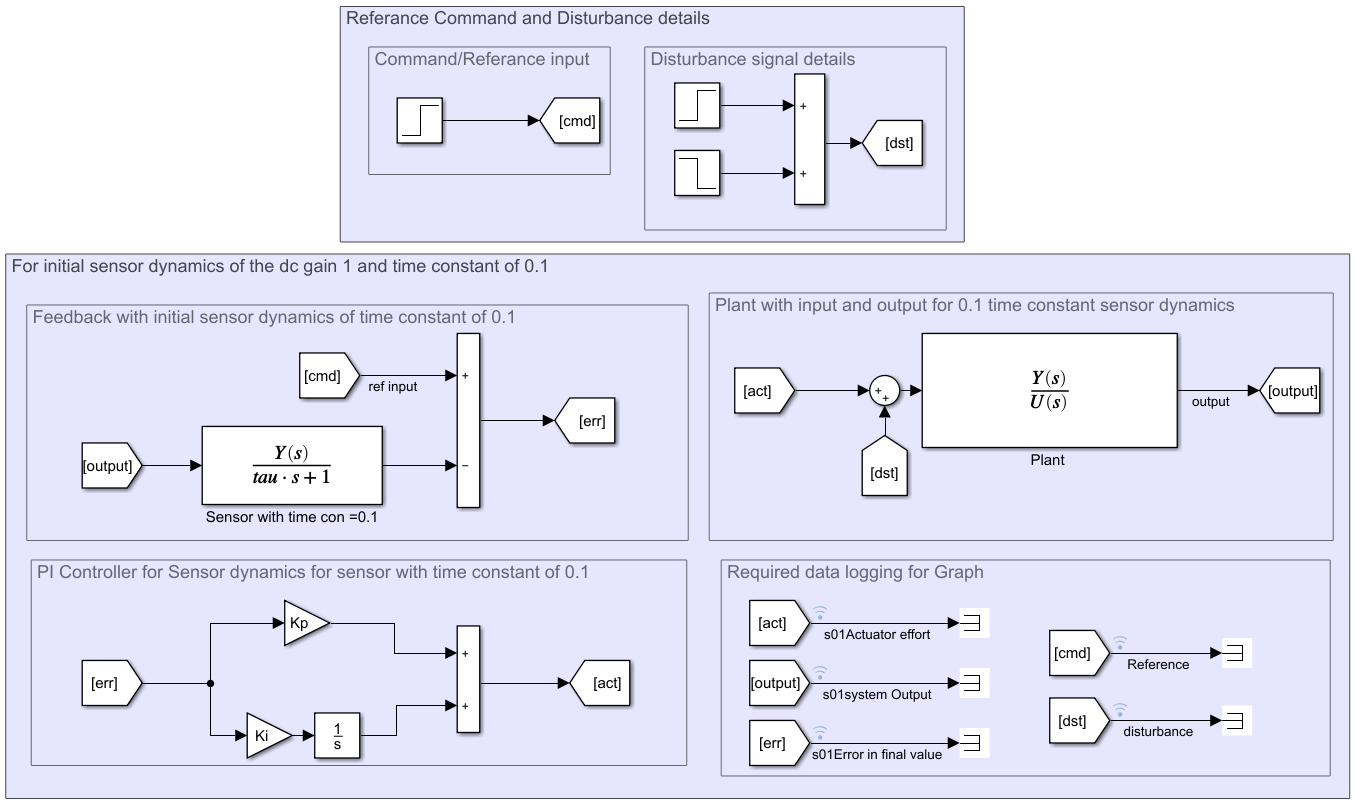

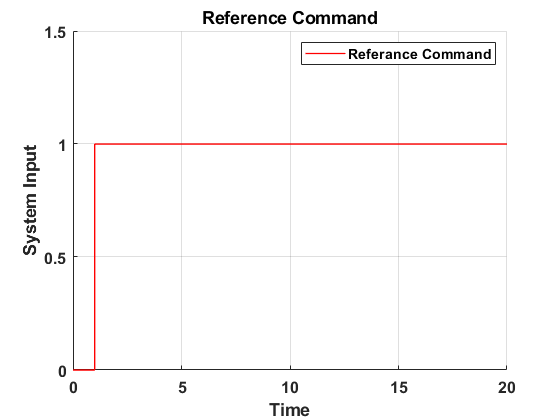

% Getting data for the step input command details to the system
% Step Command Details
s.T0 = 1;                   % Step Start time
s.A = 1;                    % Amplitude of the step
d.T0 = 7;                   % time for introduction of disturbance 
                            % after system is in staedy state
d.Tr = 5;                   % Duration of the disturbance required
d.A = 0.1;                  % Amplitude of the disturbance

% Gains finalised for the system
Kp = 0.025;                 % Finalised values for the K_p after iterations
Ki = 1.2;                   % Finalised value of K_i after the iterations

%% Setting up the model parameters required
mName = 'p2Sim';            % Name for the final model for sensor dynamics 
                            % and disturbance details
open_system(mName)          % Opening the model
Simulink.sdi.clear          % Clearing initial data in simulink

%% Running Simulations
s.TFinal = d.T0+d.Tr+8;                         % time for running simulatons in sec
s.Tstep = Tstep/2;                              % AS designed for error less than
                                                % 1% in the simulink model
                                                % with Euler integration as
                                                % type for integration
sOut = sim('p2Sim','SignalLoggingName','sdat'); % Executing simulations

% Getting Data from Simulink Model and plotting the result
% Defining indices from the Simulink
ref_signal = 7;                                 % details of input Signal Provided 
                                                % to the system 
S01actuator = 4;                                % Actuator Effort with sensor 2
S01Response = 5;                                % System response with sensor 2
S01err = 6;                                     % error in the system value with sensor 1
dist = 8;                                       % Disturbance in the system

%Plot Parameters
LW=1;                                               %linewidth
FS= 12;                                             %Fontsize
FILETYPE= '-depsc';                                 %graphic file type
FNAME1 = 'Reference Command';                       %filename for input details 
FNAME2 = 'System response for Sensor 1(tau = 0.1)'; %filename for system response
FNAME3 = 'Actuator effort for sensor 1(tau = 0.1)'; %filename for actuator effort
FNAME4 = 'Error in I/P and O/P for Sensor 1(tau=0.1)';%filename for error
FNAME5 = 'Disturbance details';                     %filename for input details 

%Grab data fro plotting from simulink
t = sOut.sdat{ref_signal}.Values.Time;         % Time details for simulations
s01i=sOut.sdat{ref_signal}.Values.Data;        % refernce signal
s01a=sOut.sdat{S01actuator}.Values.Data;       % actuator response
s01o=sOut.sdat{S01Response}.Values.Data;       % syatem response
s01e=sOut.sdat{S01err}.Values.Data;            % srror with sensor 1
s01d=sOut.sdat{dist}.Values.Data;              % srror with sensor 1

%Defining plot ids based on data required
id1=1;                                        %plot id for refernce command details
id2=2;                                        %plot id for system response with sensor 1  
id3=3;                                        %plot id for Acuator Effort with sensor 1  
id4=4;                                        %plot id for error details with sensor 1
id5=5;                                        %Plot id for disturbance details

% For plot 1 Input command with disturbance details for sensor of time constant 0.1 
h(id1).fig =figure(id1);                      % makeing figure
h(id1).axs =axes;                             % Make axies
h(id1).ln(1)=line(t,s01i,'Color','r');        % stable system
h(id1).xlb = xlabel('Time');                  % Xlabel for plot1
h(id1).ylb = ylabel('System Input');          % Ylabel for plot1
h(id1).leg = legend('Referance Command');     % legends
ylim([0 1.5])                                 % Limits for y axis for proper representation
h(id1).tit = title(FNAME1);                   % title for plot
%Plot formatting
for i=1:length(h(id1).ln)                     % Setting linewidth for first plot
    h(id1).ln(i).LineWidth = LW;
end
h(id1).axs.FontSize   = FS;                   % axis font size for first plot
h(id1).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

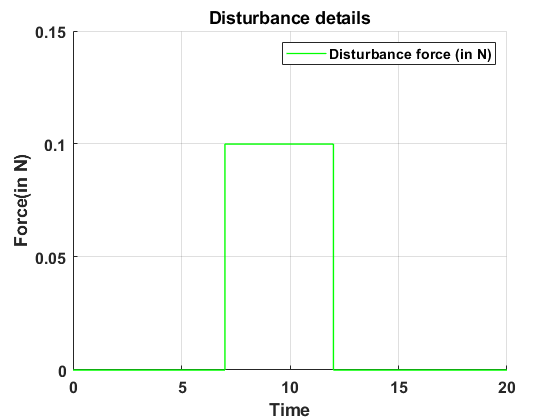

% For plot 5 Disturbance in the system 
h(id5).fig =figure(id5);                      % makeing figure
h(id5).axs =axes;                             % Make axies
h(id5).ln(1)=line(t,s01d,'Color','g');        % response for unity
h(id5).xlb = xlabel('Time');                  % Xlabel for plot1
h(id5).ylb = ylabel('Force(in N)');           % Ylabel for plot1
h(id5).leg = legend('Disturbance force (in N)');% Check value for legend
ylim([0 0.15])                                % Limits for y axis for proper representation
h(id5).tit = title(FNAME5);                   % title for plot
%Plot formatting
for i=1:length(h(id5).ln)                     % Setting linewidth for first plot
    h(id5).ln(i).LineWidth = LW;
end
h(id5).axs.FontSize   = FS;                   % axis font size for first plot
h(id5).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Above figure shows the details of the disturbance provided in the system as per requirement. Disturbance is introduced at 7sec, so that system is stable after settling within 1% for 3sec and response of the system to disturbance can be properly measured.

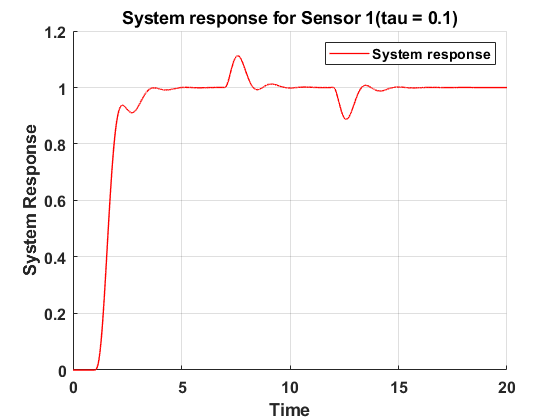

% For plot 2 System response with sensor of time constant 0.1 
h(id2).fig =figure(id2);                        % makeing figure
h(id2).axs =axes;                               % Make axies
h(id2).ln(1)=line(t,s01o,'Color','r');          % stable system
h(id2).xlb = xlabel('Time');                    % Xlabel for plot1
h(id2).ylb = ylabel('System Response');         % Ylabel for plot1
h(id2).leg = legend('System response');         % legends
h(id2).tit = title(FNAME2);                     % title for plot
%Plot formatting
for i=1:length(h(id2).ln)                       % Setting linewidth for first plot
    h(id2).ln(i).LineWidth = LW;
end
h(id2).axs.FontSize   = FS;                     % axis font size for first plot
h(id2).axs.FontWeight = 'Bold';                 % Set axis type for first plot
grid;

S01.Overshoot

ans = 0.0404

S01.SettlingTime

ans = 2.4679

Figure above provide the response of the system with designed controller and from the graph it can be observed that system is having the overshoot is 0.0404% against requirement of less than 5% and settling time is 2.4679sec for 1% settling against requirement of the less than 3 sec, and steady state error is also zero against the requirement of the less than 5% of the input.

With disturbance as discussed earlier, system is also type 1 with respect to disturbance. Hence steady state error will become zero ultimately with respect to the disturbance too. From the graph above as the disturbance is introduced at time 7sec, when system is in steady state and due to disturbance, there observed to be variation in the system but the system regains its original output location by rejecting the disturbance introduced. High overshoot observed than initial response of about 11.2% due to disturbance and system is getting settled at around 3 sec after the disturbance also for designed controller.

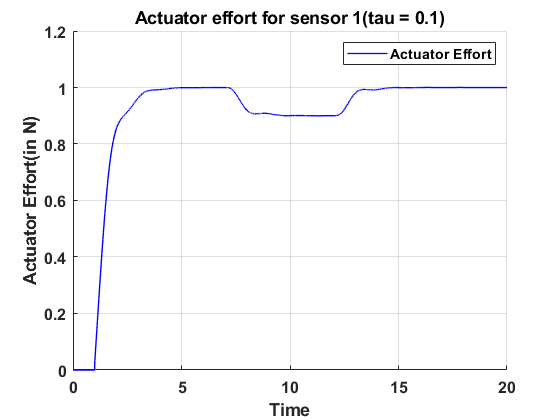

% For plot 3 Actuator effort with sensor of time constant 0.1 
h(id3).fig =figure(id3);                        % makeing figure
h(id3).axs =axes;                               % Make axies
h(id3).ln(1)=line(t,s01a,'Color','b');          % stable system
h(id3).xlb = xlabel('Time');                    % Xlabel for plot1
h(id3).ylb = ylabel('Actuator Effort(in N)');   % Ylabel for plot1
h(id3).leg = legend('Actuator Effort');         % legends
h(id3).tit = title(FNAME3);                     % title for plot
%Plot formatting
for i=1:length(h(id3).ln)                       % Setting linewidth for first plot
    h(id3).ln(i).LineWidth = LW;
end
h(id3).axs.FontSize   = FS;                     % axis font size for first plot
h(id3).axs.FontWeight = 'Bold';                 % Set axis type for first plot
grid;

Figure above provide the actuator effort required for the system to achieve requirements provided. Limitation of the actuator was maximum effort it can provide was $\frac{+}{}2.5N$, from the graph above actuator efforts are around $1N$, which is well within the limits of the system. As at time of around 4 sec, system become stable hence, actuator effort also remains at the constant value till 7sec, when there observed variations in the actuator effort which are with respect to the disturbance coming to the system and it can be observed that as the discturbance is assisting the actuator's direct of control, actuator effort required is reduced by the same value as that of the disturbance. At 12 sec, when disturbance goes out of the system, actuator effort comes back to the original value as that of earlier.

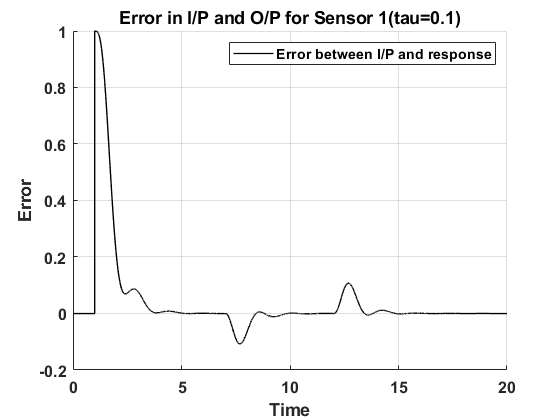

% For plot 4 Error analuysis with respect to input to the system 
h(id4).fig =figure(id4);                    % makeing figure
h(id4).axs =axes;                           % Make axies
h(id4).ln(1)=line(t,s01e,'Color','k');      % stable system
h(id4).xlb = xlabel('Time');                % Xlabel for plot1
h(id4).ylb = ylabel('Error');               % Ylabel for plot1
h(id4).leg = legend('Error between I/P and response');% legends
h(id4).tit = title(FNAME4);                 % title for plot
%Plot formatting
for i=1:length(h(id4).ln)                   % Setting linewidth for first plot
    h(id4).ln(i).LineWidth = LW;            
end
h(id4).axs.FontSize   = FS;                 % axis font size for first plot
h(id4).axs.FontWeight = 'Bold';             % Set axis type for first plot
grid;

Figure above provide the details for the steady state error of the system, as during the design PI controller was selected to achieve the requirement of having steady state error as zero against requirement of less than 5% of the input. And as mentioned during design, with PI controller steady state error will be zero, same can be seen in the graph above, error reduces to zero once the system achieves the steady state. At time 7sec, there observed to be variations in the system which are due to introduction of the disturbance in the system. As system is of type 1 with respect to disturbance also, hence after the disturbance also error goes to zero.

## Validating control system for sensor 2 with time constant of 0.2

Below are the details of the part of Simulink model used for checking performance for the second sensor-

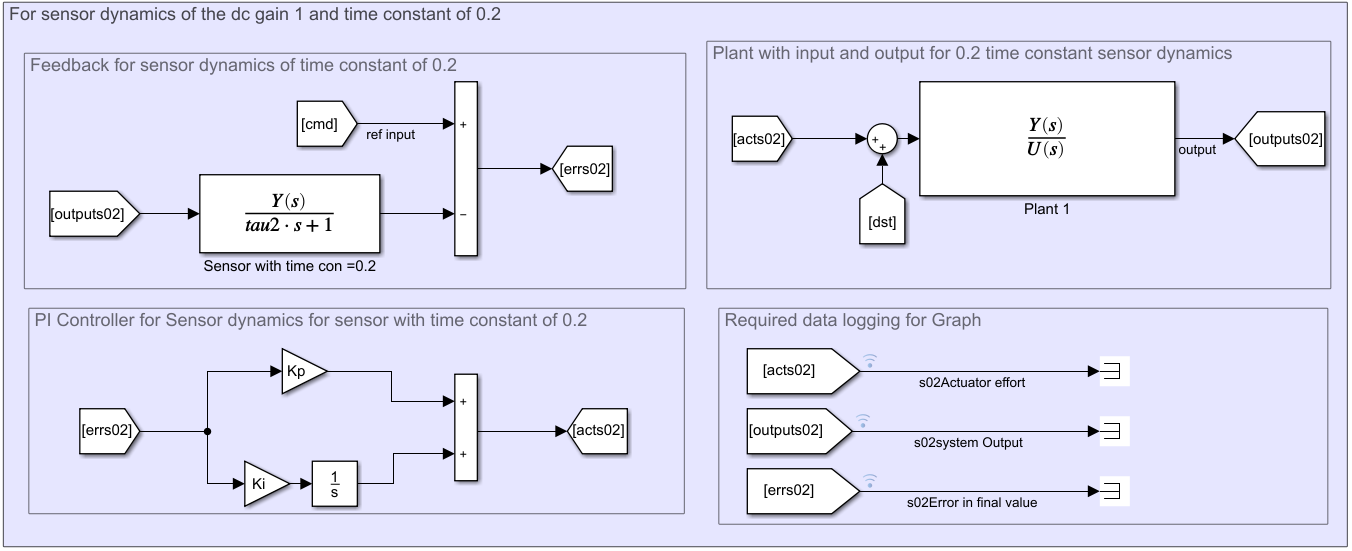

Below are the code details used for validating whether sensor meets the requirement specified earlier-

%% Step response by the sensor 2 with time constant of 0.2 and DC gain of 1
mytfcls02 = feedback(PI*mytfpl,mytfs2); % Preparing close loop transfer 
                                        % function with sensor 2
% Getting reponse for the step command
S02 = stepinfo(mytfcls02,'SettlingTimeThreshold',ST); % Getting Step response data
S02.Overshoot

ans = 1.8074

S02.SettlingTime

ans = 2.3553

System observed to be achieving the requirements with new sensor for the same gain values of PI controller  hence controller selected can be used for new sensor without change.

Using simulations results below to validate the same-

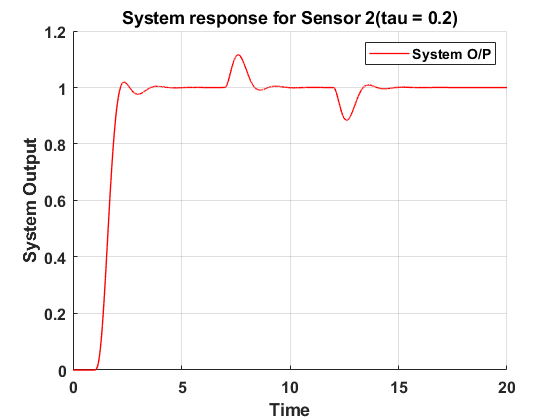

% Getting Data from Simulink Model and plotting the result
% Defining indices from the Simulink
S02actuator = 1;                                % Actuator Effort with sensor 2
S02Response = 2;                                % System response with sensor 2
S02err = 3;                                     % error in the system value with sensor 2

%Plot Parameters
FNAME6 = 'System response for Sensor 2(tau = 0.2)'; %filename for sensor response 
FNAME7 = 'Actuator effort for sensor 2(tau = 0.2)'; %filename for actuator effort
FNAME8 = 'Error in I/P and O/P for Sensor 2(tau=0.2)';%filename for error

%Defining plot ids based on data required
id6=6;                                        %plot id for system response with sensor 2
id7=7;                                        %plot id for Acuator Effort with sensor 2
id8=8;                                        %plot id for error details with sensor 2

%Grab data fro plotting from simulink
s02a=sOut.sdat{S02actuator}.Values.Data;       % actuator response with sensor 2
s02o=sOut.sdat{S02Response}.Values.Data;       % system response with sensor 2
s02e=sOut.sdat{S02err}.Values.Data;            % error with sensor 2

% For plot 6 System response for the sensor with time constant of 0.2 
h(id6).fig =figure(id6);                    % makeing figure
h(id6).axs =axes;                           % Make axies
h(id6).ln(1)=line(t,s02o,'Color','r');      % stable system
h(id6).xlb = xlabel('Time');                % Xlabel for plot1
h(id6).ylb = ylabel('System Output');       % Ylabel for plot1
h(id6).leg = legend('System O/P');% legends
h(id6).tit = title(FNAME6);                 % title for plot
%Plot formatting
for i=1:length(h(id6).ln)                   % Setting linewidth for first plot
    h(id6).ln(i).LineWidth = LW;            
end
h(id6).axs.FontSize   = FS;                 % axis font size for first plot
h(id6).axs.FontWeight = 'Bold';             % Set axis type for first plot
grid;

S02.Overshoot

ans = 1.8074

S02.SettlingTime

ans = 2.3553

With new sensor of time constant of 0.2, with designed PI controller with gain values of $K_p$ as 0.025 and $K_i$ as 1.2, system observed to be having the settling time ($t_s$) with in 3sec for 1% settling and overshoot ($\%MP$) of less than 5% and steady state error for the step input zero against required $e_{ss}<5\%$.

At time 7 sec, with introduction of disturbance there observed to be overshoot which is higher than initial sensor in same trend with initial response and system settling to zero steady state error.

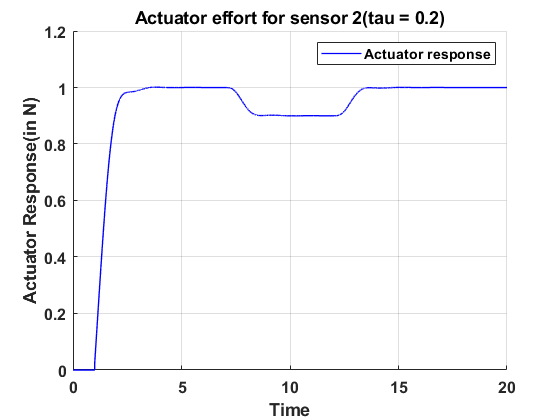

% For plot 7 actuator effort for the sensor with time constant of 0.2 
h(id7).fig =figure(id7);                    % makeing figure
h(id7).axs =axes;                           % Make axies
h(id7).ln(1)=line(t,s02a,'Color','b');      % stable system
h(id7).xlb = xlabel('Time');                % Xlabel for plot1
h(id7).ylb = ylabel('Actuator Response(in N)');% Ylabel for plot1
h(id7).leg = legend('Actuator response');% legends
h(id7).tit = title(FNAME7);                 % title for plot
%Plot formatting
for i=1:length(h(id7).ln)                   % Setting linewidth for first plot
    h(id7).ln(i).LineWidth = LW;            
end
h(id7).axs.FontSize   = FS;                 % axis font size for first plot
h(id7).axs.FontWeight = 'Bold';             % Set axis type for first plot
grid;

With new sensor actuator effort remined nearly same as that of the initial sensor, making sense as we have not changed the gain values, causing no change in actuator efforts. There observed variation as we introduce the disturbance in the system.

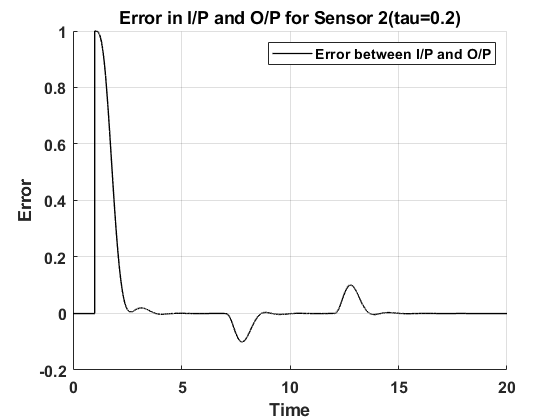

% For plot 8 error for the sensor with time constant of 0.2 
h(id8).fig =figure(id8);                    % makeing figure
h(id8).axs =axes;                           % Make axies
h(id8).ln(1)=line(t,s02e,'Color','k');      % stable system
h(id8).xlb = xlabel('Time');                % Xlabel for plot1
h(id8).ylb = ylabel('Error');       % Ylabel for plot1
h(id8).leg = legend('Error between I/P and O/P');% legends
h(id8).tit = title(FNAME8);                 % title for plot
%Plot formatting
for i=1:length(h(id8).ln)                   % Setting linewidth for first plot
    h(id8).ln(i).LineWidth = LW;            
end
h(id8).axs.FontSize   = FS;                 % axis font size for first plot
h(id8).axs.FontWeight = 'Bold';             % Set axis type for first plot
grid;

As earlier found out system is stable with the designed controller and reaching to steady state error of zero same observed after changing the sensor dynamics, after settling at time 7sec when disturbance is introduced in the system, error is introduced and reduced to zero eventually as system in type 1 with respect to disturbance.

## Summary

For designing the controller with sensor in feedback path, initially range for proportional controller in loop with system was checked for with sensor and without sensor. Range for gain observed to be reduced substantially when provided with the sensor in feedback path as compared to unity feedback. To design controller one way was to neglect sensor dynamics by considering the pole being added is far of in LHP and once the design with unity feedback is available, alter the gain to satisfy the system requirement with sensor and varying values of gain. But with proportional controller, with substantial reduction in range for proportional gain for stability approach chosen was to design control law with sensor dynamics, which will not require final altering of the gains.

For starting point, only proportional controller was chosen to obtain the required response, but with only proportional controller, to achieve steady state error less than 5% which was requirement, range of proportional gain observed to be out of the stability range for the system. Hence to satisfy the requirement PI controller was chosen, which adds poles at origin, making system type 1 with respect to input reference for unity feedback, hence making steady state error for step input zero, which is within range of required 5% of the final value. With sensor, type of the system checked to be sure about adding the PI controller to achieve the steady state error requirement. Once steady state error requirement was met, closed loop characteristic equation was prepared to obtain the conditions for stability of the system to iterate values of the gains of the PI controller to satisfy the other requirements. As with PI controller and sensor in the system, obtaining PI values from the second order characteristic equation became difficult. Hence manual tuning was done with help of the code provided and iterated for various values of $K_p$ and $K_i$ by observing there effect on the remaining requirements for the settling time ($t_s$) and % overshoot ($\%MP$), once the values finalised, Simulink model was prepared to check the response is proper or not and verify for the actuator effort.

Before starting for the Simulink execution, effect of the disturbance on the system was checked for steady state error and system observed to be type 1 with PI controller and sensor in loop, hence steady state error after the disturbance observed to be zero.

For the simulation, error for the simulation assumed to be less than 1%, and integration step size calculated for the same with maximum eigen value formula. And step size selected as 0.001 (against required $T<0.0021$) with Euler integration method for same.

From simulations, as per design trend observed similar for the design requirements, steady state error was zero against requirement of $e_{ss}<5\%$, and settling time ($t_s$) observed to be 2.4679sec against requirement of less than 3 sec for 1% settling time and overshoot observed to be 0.0404% against requirement of $\%MP<5\%$.

Same controller system was deployed for the second sensor with time constant of 0.2, and it observed to be satisfying the requirements provided for system with increased over shoot of 1.8074% from the earlier 0.0404% and settling time observed to be 2.3553sec against earlier settling time of 2.4679sec.

Other approaches tried were using the state feedback controller for the system, with the single output coming out from the system after the sensor, issue was observed in getting the original two states available in system. Which can be resolved with use of the estimator like Kalman filter, state space feedback method provide the flexibility to place the poles at desired location with MATLAB command and getting out the corresponding gain. With proportional plus rate controller system design can be done using the proportional plus rate controller, but higher gains of the $K$and $K_d$ are required to achieve the requirements exceeding the actuator effort required and require the saturator in model. to avoid saturation.